t5=[0,0.83,1.29,1.66];
y5=[-0.69,-1.49,-1.63,-1.69];

t1=[0,0.81,1.25,1.59,1.89,2.15];
y1=[-0.49,-1.19,-1.41,-1.52,-1.59,-1.62];

t05=[0,0.77,1.20,1.57,1.86,2.12];
y05=[2.22,1.16,0.68,0.42,0.28,0.2];

t005=[0,0.74,1.2,1.54,1.84];
y005=[1.42,0.94,0.56,0.4,0.3];

t0=[0,0.84,1.32,1.64];
y0=[0.42,0.28,0.22,0.16];

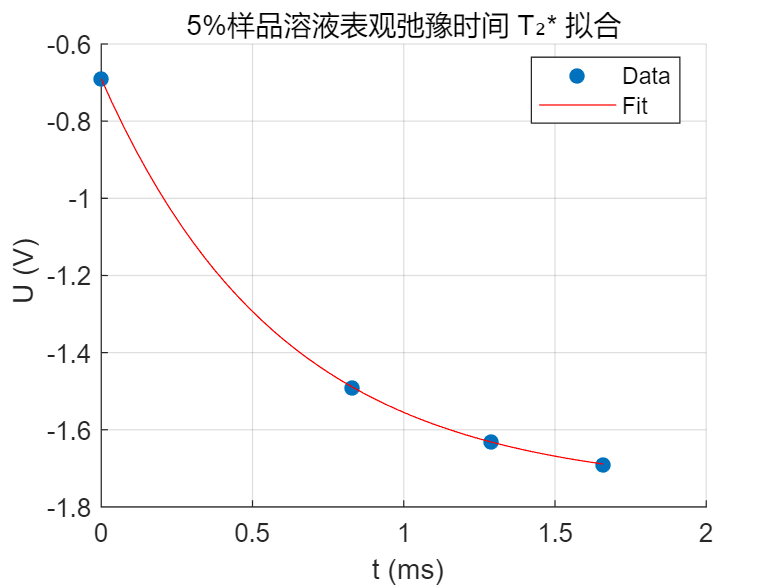

% 假设 t 和 y 是你的离散数据点
t = t5;
y = y5;

% 定义拟合函数类型
fitfunc = fittype('a * exp(-t/T) + c', 'independent', 't', 'coefficients', {'a', 'T', 'c'});

% 使用 fit 函数进行拟合
fittedmodel = fit(t', y', fitfunc, 'StartPoint', [1, 1, 1]);

f1=fittedmodel;
% 获取拟合参数
a = fittedmodel.a;
T = fittedmodel.T;
c = fittedmodel.c;

% 绘制散点图和拟合曲线
figure;
scatter(t, y, 'filled', 'DisplayName', 'Data');
hold on;
fplot(@(t) a * exp(-t/T) + c, [min(t), max(t)], 'r', 'DisplayName', 'Fit');
hold off;

title('5%样品溶液表观弛豫时间 T₂* 拟合');

% 其他图形元素，同样适用Unicode字符
xlabel(' t (ms)');
ylabel(' U (V)');
legend('Location','best');
grid on;


f1.a

ans = 1.0652

f1.T

ans = 0.5984

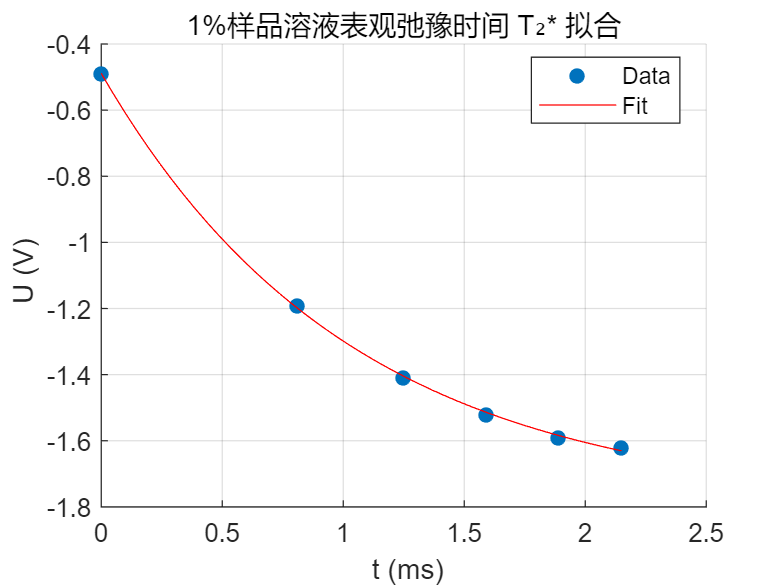

% 假设 t 和 y 是你的离散数据点
t = t1;
y = y1;

% 定义拟合函数类型
fitfunc = fittype('a * exp(-t/T) + c', 'independent', 't', 'coefficients', {'a', 'T', 'c'});

% 使用 fit 函数进行拟合
fittedmodel = fit(t', y', fitfunc, 'StartPoint', [1, 1, 1]);

f2=fittedmodel;
% 获取拟合参数
a = fittedmodel.a;
T = fittedmodel.T;
c = fittedmodel.c;

% 绘制散点图和拟合曲线
figure;
scatter(t, y, 'filled', 'DisplayName', 'Data');
hold on;
fplot(@(t) a * exp(-t/T) + c, [min(t), max(t)], 'r', 'DisplayName', 'Fit');
hold off;

title('1%样品溶液表观弛豫时间 T₂* 拟合');

% 其他图形元素，同样适用Unicode字符
xlabel(' t (ms)');
ylabel(' U (V)');
legend('Location','best');
grid on;


f2.a

ans = 1.3031

f2.T

ans = 1.0295

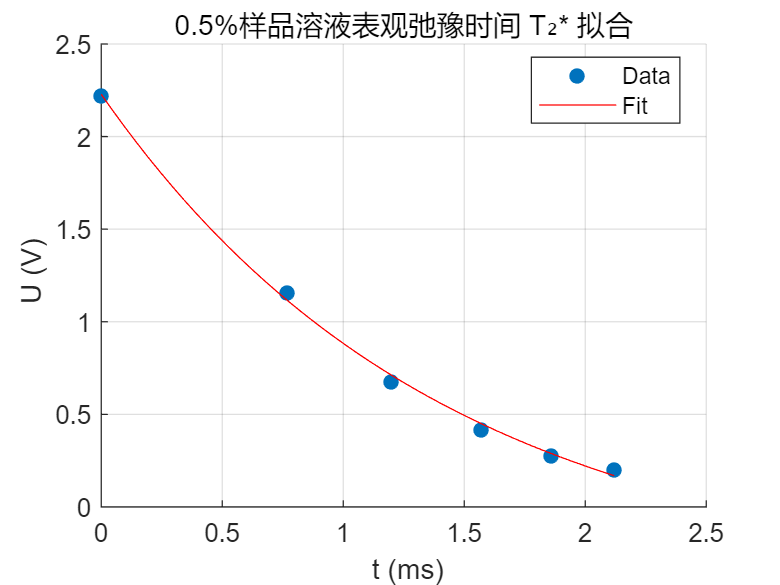

% 假设 t 和 y 是你的离散数据点
t = t05;
y = y05;

% 定义拟合函数类型
fitfunc = fittype('a * exp(-t/T) + c', 'independent', 't', 'coefficients', {'a', 'T', 'c'});

% 使用 fit 函数进行拟合
fittedmodel = fit(t', y', fitfunc, 'StartPoint', [1, 1, 1]);

f3=fittedmodel;
% 获取拟合参数
a = fittedmodel.a;
T = fittedmodel.T;
c = fittedmodel.c;

% 绘制散点图和拟合曲线
figure;
scatter(t, y, 'filled', 'DisplayName', 'Data');
hold on;
fplot(@(t) a * exp(-t/T) + c, [min(t), max(t)], 'r', 'DisplayName', 'Fit');
hold off;

title('0.5%样品溶液表观弛豫时间 T₂* 拟合');

% 其他图形元素，同样适用Unicode字符
xlabel(' t (ms)');
ylabel(' U (V)');
legend('Location','best');
grid on;


f3.a

ans = 2.6492

f3.T

ans = 1.4108

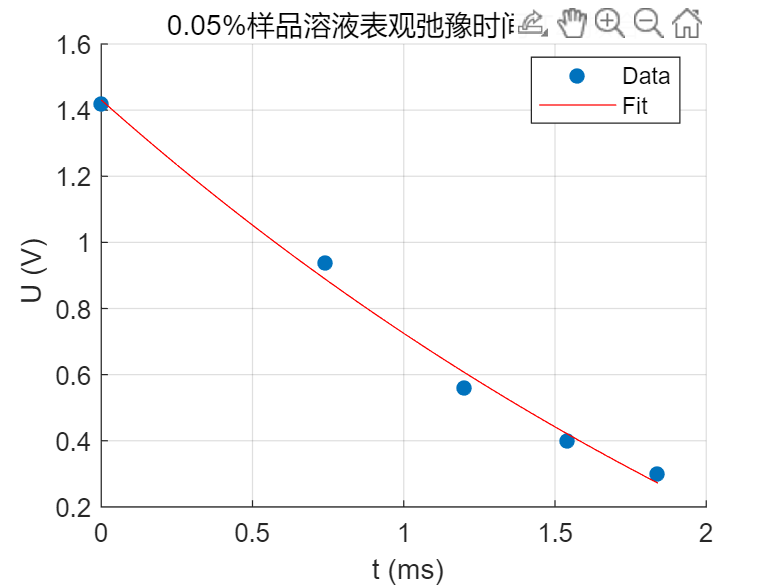

% 假设 t 和 y 是你的离散数据点
t = t005;
y = y005;

% 定义拟合函数类型
fitfunc = fittype('a * exp(-t/T) + c', 'independent', 't', 'coefficients', {'a', 'T', 'c'});

% 使用 fit 函数进行拟合
fittedmodel = fit(t', y', fitfunc, 'StartPoint', [1, 1, 1]);

f4=fittedmodel;
% 获取拟合参数
a = fittedmodel.a;
T = fittedmodel.T;
c = fittedmodel.c;

% 绘制散点图和拟合曲线
figure;
scatter(t, y, 'filled', 'DisplayName', 'Data');
hold on;
fplot(@(t) a * exp(-t/T) + c, [min(t), max(t)], 'r', 'DisplayName', 'Fit');
hold off;

title('0.05%样品溶液表观弛豫时间 T₂* 拟合');

% 其他图形元素，同样适用Unicode字符
xlabel(' t (ms)');
ylabel(' U (V)');
legend('Location','best');
grid on;


f4.a

ans = 2.7948

f4.T

ans = 3.4359

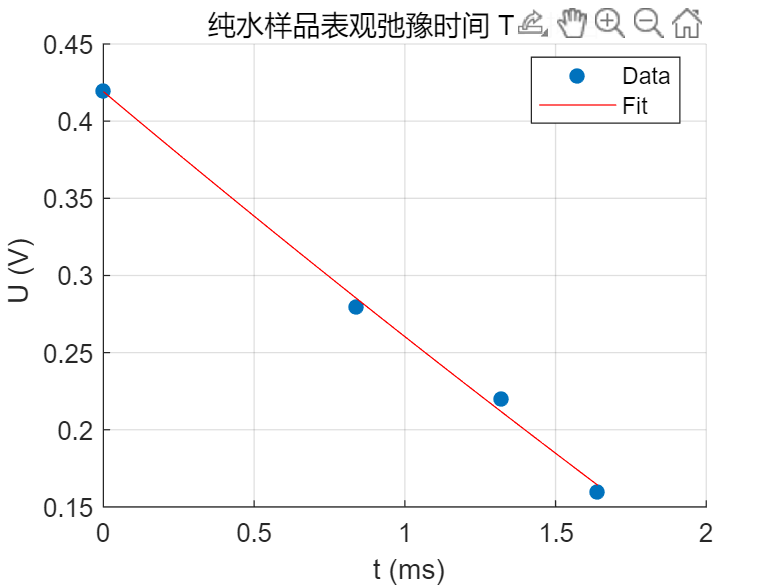

% 假设 t 和 y 是你的离散数据点
t = t0;
y = y0;

% 定义拟合函数类型
fitfunc = fittype('a * exp(-t/T) + c', 'independent', 't', 'coefficients', {'a', 'T', 'c'});

% 使用 fit 函数进行拟合
fittedmodel = fit(t', y', fitfunc, 'StartPoint', [1, 1, 1]);

f5=fittedmodel;
% 获取拟合参数
a = fittedmodel.a;
T = fittedmodel.T;
c = fittedmodel.c;

% 绘制散点图和拟合曲线
figure;
scatter(t, y, 'filled', 'DisplayName', 'Data');
hold on;
fplot(@(t) a * exp(-t/T) + c, [min(t), max(t)], 'r', 'DisplayName', 'Fit');
hold off;

title('纯水样品表观弛豫时间 T₂* 拟合');

% 其他图形元素，同样适用Unicode字符
xlabel(' t (ms)');
ylabel(' U (V)');
legend('Location','best');
grid on;


f5.a

ans = 2.4980

f5.T

ans = 15.2266

UMs=[f5.a,f4.a,f3.a,f2.a,f1.a];
T2s=[f5.T,f4.T,f3.T,f2.T,f1.T];
concentration=[0,0.05,0.5,1,5];
T=table(concentration',UMs', T2s', 'VariableNames', {'Concentration','Amplitude', 'Time'});

disp(T)

    Concentration    Amplitude     Time  
    _____________    _________    _______

           0           2.498       15.227
        0.05          2.7948       3.4359
         0.5          2.6492       1.4108
           1          1.3031       1.0295
           5          1.0652      0.59837



writetable(T, 'output.xls');

for i=1:length(t5)
    DeltaBbyB(i)=2*pi*50*log((y5(i)-f1.c)./(0.06529))./(21.4655*10^6)./asin((1.66-t5(i))/2.68);
end
DeltaBbyB

DeltaBbyB = 1.0e-04 *

    0.6118    0.6516    0.6887      -Inf



2*pi*50*log((1.0629)./(0.06529))./(21.4655*10^6)./asin(1.66/2.68)

ans = 6.1127e-05

y5(1)-f1.c

ans = 1.0653